# Proyecto Global de Asignatura

## Rubén A. y David A. - Otoño 2024

clear;
decimales = 5;             % Decimales a mostrar
muestras_para_media = 50;  % Muestras del final de las respuestas a tener en cuenta para las medias
aproximacion = -3;         % Aproximación del ln(0.05)

## Fase 1 - Caracterización de la planta

**Ejercicio 1**

Capture y caracterice la salida de la planta en función de la tensión de entrada con un procedimiento análogo al empleado en la Práctica 2 y obtenga su función de transferencia (FdeT) en las unidades que considere más adecuadas para trabajar en el desarrollo de todo el diseño. 

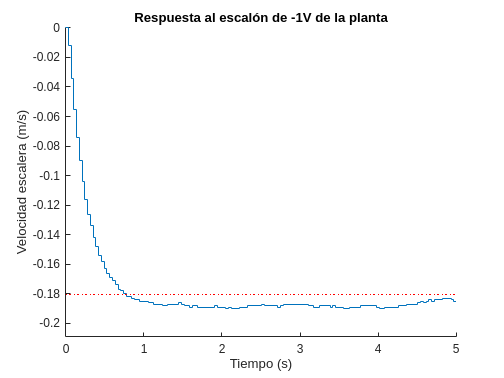

Escalón de -1 V.
	Media de las últimas 50 muestras = -0.19000 m/s
	ts  = 0.77000 s
	Km  = 0.19000 m/s/V
	tau = 0.25667 s

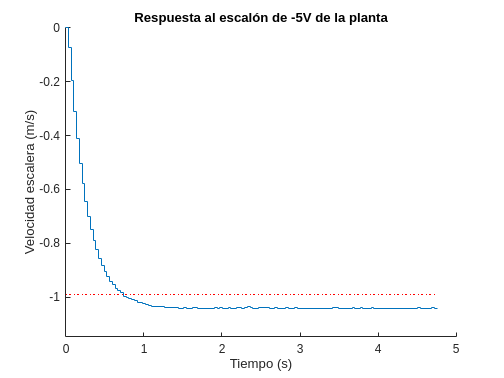

Escalón de -5 V.
	Media de las últimas 50 muestras = -1.04200 m/s
	ts  = 0.73500 s
	Km  = 0.20840 m/s/V
	tau = 0.24500 s

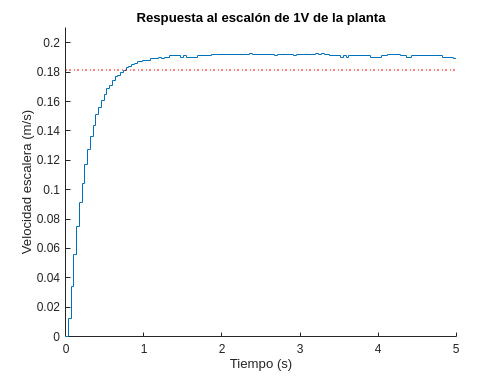

Escalón de 1 V.
	Media de las últimas 50 muestras = 0.19100 m/s
	ts  = 0.77000 s
	Km  = 0.19100 m/s/V
	tau = 0.25667 s

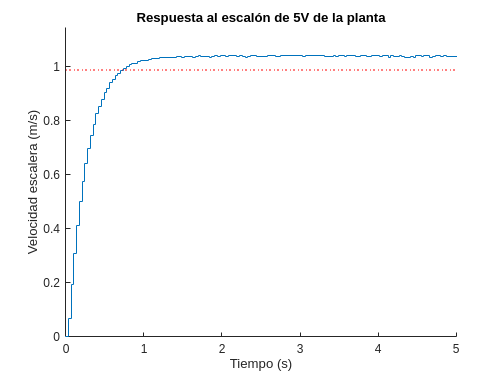

Escalón de 5 V.
	Media de las últimas 50 muestras = 1.04000 m/s
	ts  = 0.73500 s
	Km  = 0.20800 m/s/V
	tau = 0.24500 s

ficheros = dir("Fase1/sin_perturbacion/");

funciones_de_transferencia = {};
Kms  = {};
taus = {};
tiempos_de_interes = {};
salidas_de_interes = {};
amplitudes_escalon = {};

for i = 1:length(ficheros)
    fichero = ficheros(i).name;
    
    % Saltar '.' y '..'
    if strcmp(fichero, '.') || strcmp(fichero, '..')
        continue;
    end
    str_amplitud_escalon = strsplit(fichero, '_'); str_amplitud_escalon = str_amplitud_escalon{end};
    amplitud_escalon = str2double(regexprep(str_amplitud_escalon, '[^-\d]', ''));

    escalon_sin_perturbacion = load("Fase1/sin_perturbacion/" + fichero);
    Ts = 35e-3;
    
    tiempo     = escalon_sin_perturbacion(:, 1);
    referencia = escalon_sin_perturbacion(:, 2);
    salida     = escalon_sin_perturbacion(:, 3);
    
    x_ini = find(abs(referencia) > 0, 1, 'first') + 1; % Se suma 1 ya que se tienen dos retardos y se va a trabajar 
                                                       % con una aproximación de primer orden
    x_fin = length(referencia);
    
    t_ini = tiempo(x_ini);
    t_fin = tiempo(end);
    
    t_interes = tiempo(x_ini:x_fin) - tiempo(x_ini);
    c_interes = salida(x_ini:x_fin);
    
    tiempos_de_interes{end + 1} = t_interes;
    salidas_de_interes{end + 1} = c_interes;
    amplitudes_escalon{end + 1} = amplitud_escalon;

    c_inf = mean(c_interes(end-muestras_para_media, end));
    
    ks = find(abs(c_interes) >= abs(0.95*c_inf), 1, 'first') - 1;
    ts = ks*Ts;
    
    figure
    hold on
    stairs(t_interes, c_interes)
    plot([0 t_fin - t_ini], 0.95*c_inf*[1 1], 'r:')
    xlim([0 5])
    ylim(1.1 * [min(0, c_inf) max(0, c_inf)])
    title("Respuesta al escalón de " + str_amplitud_escalon + " de la planta")
    xlabel("Tiempo (s)")
    ylabel("Velocidad escalera (m/s)")
    
    Km = c_inf/amplitud_escalon;
    tau = -ts/aproximacion;
    
    Kms{end + 1}  = Km;
    taus{end + 1} = tau;

    syms s
    funciones_de_transferencia{end + 1} = Km/(tau*s + 1);

    fprintf("Escalón de %d V.\n\tMedia de las últimas %d muestras = %.0" + decimales + "f m/s\n\tts  = %.0" ...
        + decimales + "f s\n\tKm  = %.0" + decimales + "f m/s/V\n\ttau = %.0" + decimales + "f s", ...
        amplitud_escalon, muestras_para_media, c_inf, ts, Km, tau)

end


fprintf("Funciones de transferencia:")

Funciones de transferencia:

vpa(funciones_de_transferencia, decimales)

$$ans = \left(\begin{array}{cccc} \frac{0.19}{0.25667\,s+1.0} & \frac{0.2084}{0.245\,s+1.0} & \frac{0.191}{0.25667\,s+1.0} & \frac{0.208}{0.245\,s+1.0} \end{array}\right)$$


fprintf("Funcion de transferencia media:")

Funcion de transferencia media:

Km  = mean(cell2mat(Kms));
tau = mean(cell2mat(taus));

syms s
G = Km/(tau*s + 1);
vpa(G, decimales)

$$ans = \frac{0.19935}{0.25083\,s+1.0}$$

fprintf("Valores de la función media:\n\tKm  = %.0" + decimales + "f m/s/V\n\ttau = %.0" + decimales + "f s", Km, tau)

Valores de la función media:
	Km  = 0.19935 m/s/V
	tau = 0.25083 s

**Ejercicio 2**

Corrobore la validez del modelo mediante su simulación en Matlab/Simulink, como también se hizo en la Práctica 2

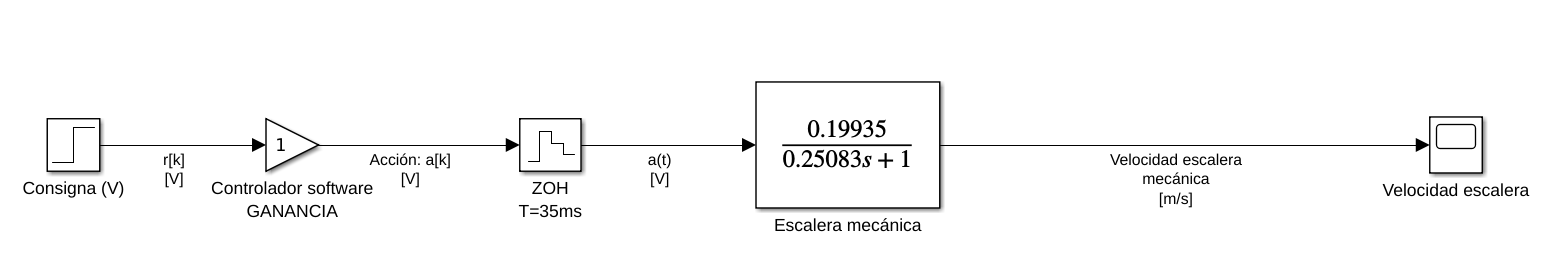

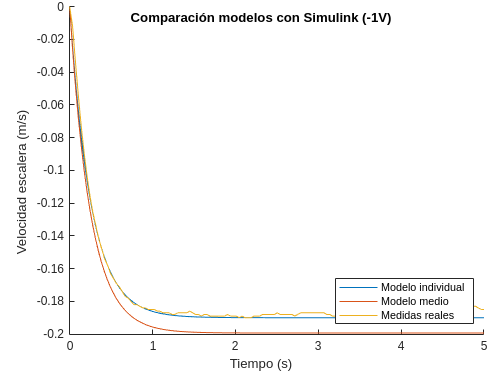

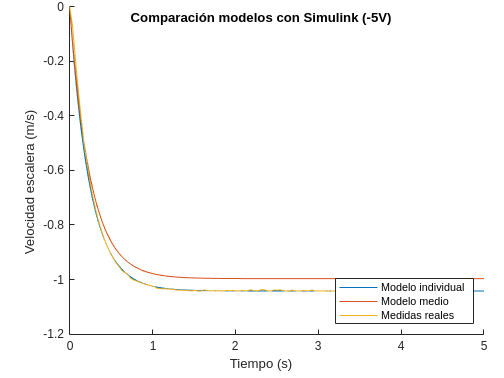

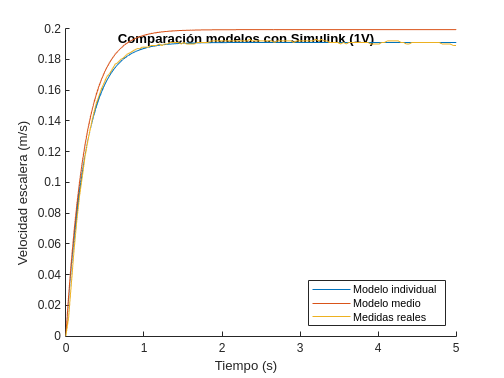

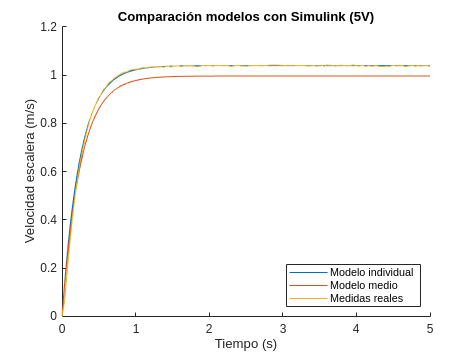

open_system("Fase1/ejercicio2")
set_param("ejercicio2/Escalera mecánica", 'Numerator', string(Km), 'Denominator', '[' + string(tau) + ' 1' + ']')

for i = 1:length(ficheros)
    fichero = ficheros(i).name;
    
    % Saltar '.' y '..'
    if strcmp(fichero, '.') || strcmp(fichero, '..')
        continue;
    end
    
    str_amplitud_escalon = strsplit(fichero, '_'); str_amplitud_escalon = str_amplitud_escalon{end};
    amplitud_escalon = str2double(regexprep(str_amplitud_escalon, '[^-\d]', ''));
    
    set_param("ejercicio2/Consigna (V)", 'After', string(amplitud_escalon))
    sim("ejercicio2")

    t_sim = salidaEscalonMotor(:, 1);
    c_sim = salidaEscalonMotor(:, 2);
    [c_ind, t_ind] = step(amplitud_escalon * tf(Kms{i - 2}, [taus{i - 2} 1]), 5);
    figure
    hold on
    title("Comparación modelos con Simulink (" + str_amplitud_escalon + ")")
    plot(t_ind, c_ind)
    plot(t_sim, c_sim)
    plot(tiempos_de_interes{i - 2}, salidas_de_interes{i - 2})
    legend('Modelo individual', 'Modelo medio', 'Medidas reales','Location','southeast')
    xlim([0 5])
    xlabel("Tiempo (s)")
    ylabel("Velocidad escalera (m/s)")
end

**Ejercicio 3**

Proponga e implemente los siguientes experimentos para caracterizar las alinealidades de la planta: 

- Para modelar la saturación excite el SM con grandes tensiones 

- Para modelar la zona muerta excite el SM con pequeñas tensiones. 

Debe de obtener los valores adecuados con sus unidades de la saturación y zona muerta, explicando el procedimiento de obtención, y añadir al modelo de Simulink los bloques de las alinealidades caracterizadas convenientemente colocadas y con coherencia de unidades. 

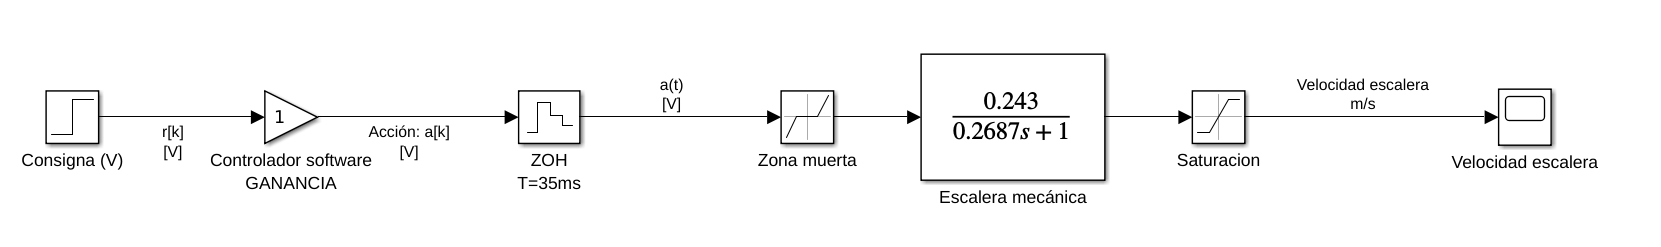

% Medida de saturación
% Se incrementa la ganancia y se pone el valor máximo de entrada. 
% Se obtiene el valor máximo de salida, que resulta ser igual para ambas direcciones.
c_max_abs = 2.11; 
fprintf("Saturación. Valor máximo de módulo de salida: |c_max| = %.02f m/s", c_max_abs)

Saturación. Valor máximo de módulo de salida: |c_max| = 2.11 m/s


% Medida de zona muerta
% Partiendo desde cero, se disminuye la ganancia y se va incrementando la entrada gradualmente hasta que se tiene movimiento (salida != 0)
deadzone_in_pos = 0.21; 
deadzone_in_neg = -0.19;
fprintf("Zona muerta. Valor mínimo de entrada. Asimétrico. DeadZone: (%.02f, %.02f) V", deadzone_in_neg, deadzone_in_pos)

Zona muerta. Valor mínimo de entrada. Asimétrico. DeadZone: (-0.19, 0.21) V


% La zona muerta resta un valor fijo a la entrada, por lo que hay que
% compensar otra vez la Km.

% Km' = salida/(entrada - deadzone) = Km/(1-dz/entrada) 
km_comps = zeros(1, length(amplitudes_escalon));
for i = 1:length(km_comps)
    if amplitudes_escalon{i} > 0
        dz = deadzone_in_pos;
    else
        dz = deadzone_in_neg;
    end

    km_comps(i) = Kms{i}/(1-dz/amplitudes_escalon{i});
end

km_comp = mean(km_comps);

fprintf("Nueva aproximación de la planta teniendo en cuenta la zona muerta [m/s/V]. Solo afecta a Km, no la tau")

Nueva aproximación de la planta teniendo en cuenta la zona muerta [m/s/V]. Solo afecta a Km, no la tau

syms s
Gcomp = km_comp/(tau*s + 1);
vpa(Gcomp, decimales)

$$ans = \frac{0.22752}{0.25083\,s+1.0}$$

**Ejercicio 4**

Calcule el equivalente discreto de la planta y caracterice teóricamente su respuesta ante entrada escalón, tanto en régimen permanente como transitorio. 

% Se añade un retraso para tener en cuenta el que se quitó en el ejercicio
% 1. Esto es debido a que la planta real es de segundo orden mientras que
% se aproxima con una de primero.

% BoG = ((1-z^(-1)) * sum_(Polos G(s)/s) Res[G(s)/(s*(1-exp(s*Ts)*z^(-1))]) * (1/z)
BoG = zpk(series(c2d(tf(Km, [tau 1]), Ts), tf(1, [1 0], Ts))) 


BoG =
 
    0.025963
  ------------
  z (z-0.8698)
 
Sample time: 0.035 seconds
Discrete-time zero/pole/gain model.
Model Properties


[~, zp, ~] = zpkdata(BoG, 'v');

c_disc_inf = dcgain(BoG); % lim(z->1) BoG
ks_disc = ceil(aproximacion / log(abs(max(zp)))) + (length(zp) - 1); % Teniendo en cuenta el retardo
ts_disc = Ts * ks_disc;

fprintf("Parámetros del BoG: \n\tc_inf = %.0" + decimales + "f m/s\n\tks = %d\n\tts = %.0"+decimales+"f s", c_disc_inf, ks_disc, ts_disc)

Parámetros del BoG: 
	c_inf = 0.19935 m/s
	ks = 23
	ts = 0.80500 s

**Ejercicio 5**

pert10personas = 0.2;

% Con el número máximo de personas, el escalón unidad no es suficiente para iniciar el movimiento positivo. 
% La perturbación máxima para el valor positivo es de -0.2m/s, valor con módulo superior a la salida frente al escalón unidad (0.1993 m/s).
c_inf_pert_pos = max([0, Km*1 - pert10personas]);
% Sin embargo, en el movimiento negativo, la perturbación ""ayuda"" a bajar, por lo que el valor final será de:
c_inf_pert_neg = min([0, Km*(-1) - pert10personas]);

fprintf("Desplazamiento con escalón de 1V y 10 personas:  c = %.02f", c_inf_pert_pos)

Desplazamiento con escalón de 1V y 10 personas:  c = 0.00

fprintf("Desplazamiento con escalón de -1V y 10 personas: c = %.02f", c_inf_pert_neg)

Desplazamiento con escalón de -1V y 10 personas: c = -0.40